# Sistem de filtrare al zgomotului de fundal dintr-o înregistrare vocală - varianta 2

## Înregistrare voce


import dsp.*
 

% Set the sampling rate
Fs = 44100;

% Set the buffer size
bufferSize = round(Fs * 0.1);  % Adjust this value as needed

% Create an audio device reader
recObj = audioDeviceReader('SampleRate', Fs, 'NumChannels', 1, 'SamplesPerFrame', bufferSize);

% Initialize a buffer for the audio data
audioData = [];

% Record 10 seconds of audio
disp('Începe înregistrarea');

Începe înregistrarea


disp('Vorbiți în microfon...');

Vorbiți în microfon...


for i = 1:100  % Adjust this value based on the buffer size
    audioData = [audioData; step(recObj)];
end

% Save the recorded audio as a WAV file
filename = 'recorded_audio.wav';
audiowrite(filename, audioData, Fs);

% Release the audio device
release(recObj);

% Display a message to indicate that the recording has been saved
disp(['Înregistrarea a fost salvată ca: ' filename]);

Înregistrarea a fost salvată ca: recorded_audio.wav


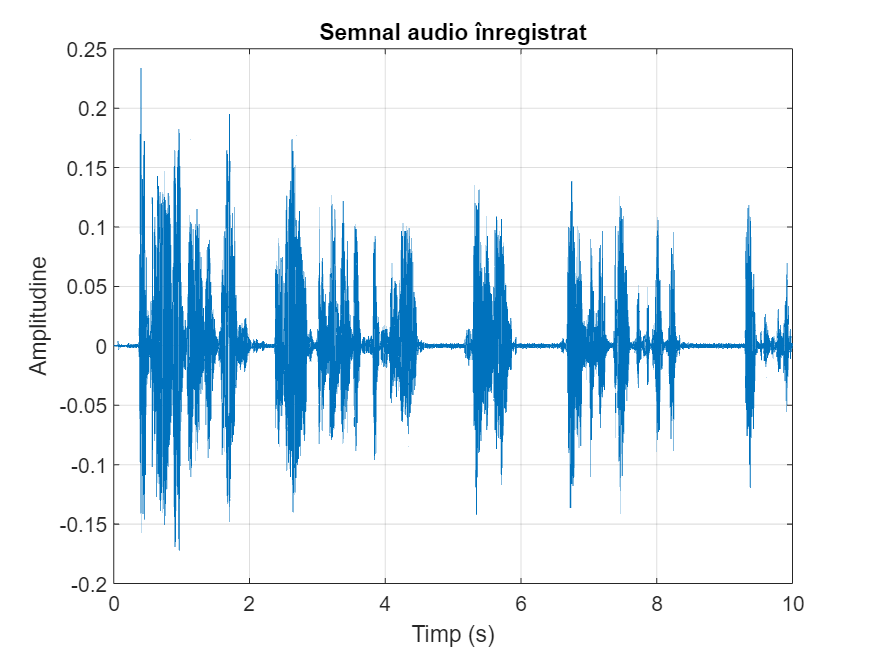


% Plot the audio signal
time = (0:length(audioData) - 1) / Fs;
figure;
plot(time, audioData);
xlabel('Timp (s)');
ylabel('Amplitudine');
title('Semnal audio înregistrat');
grid on;

warning('off', 'all');

## Adăugarea unui tip de zgomot pe canal

% Specify the full path to the .wav file
noise_type = "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren";

% Get a list of all .wav files in the folder
wav_files = dir(fullfile(noise_type, '*.wav'));

% Get the number of .wav files in the folder
num_files = length(wav_files);

% Generate a random index
rand_index = randi(num_files);

% Select a random .wav file
filename_zgomot = fullfile(noise_type, wav_files(rand_index).name);

% Display the name of the randomly selected .wav file
 disp(['Fișier selectat: ', filename_zgomot]);

    "Fișier selectat: "    "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren\93567-8-0-19.wav"



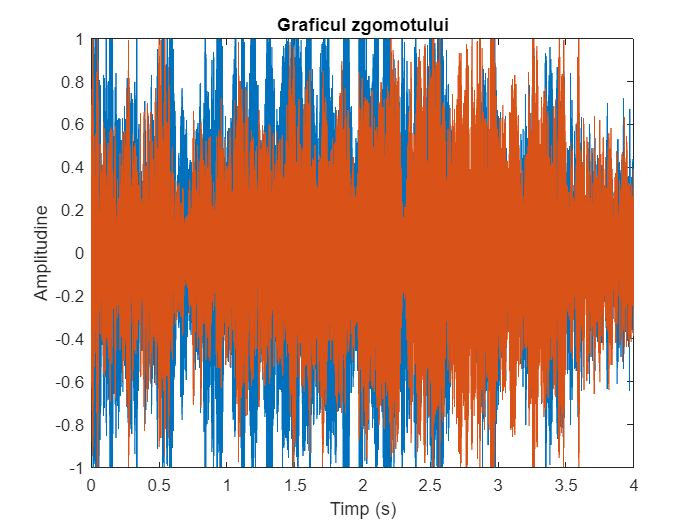


% Create a table with filename_zgomot and filename
T = table({filename_zgomot}, {filename}, 'VariableNames', {'filename_zgomot', 'filename'});

% Write the table to a CSV file
writetable(T, 'filenames_v2.csv');

% Read the .wav file
[y, Fs] = audioread(filename_zgomot);

% Create a time vector based on the data length and sample rate
t = (0:length(y)-1)/Fs;

% Plot the waveform
figure;
plot(t, y);
title('Graficul zgomotului');
xlabel('Timp (s)');
ylabel('Amplitudine');

## Suprapunere voce + zgomot

 

% Define the name of the Python script
python_script = 'Overlap2.py';

% Create the command string
command_str = ['python ', python_script];

% Call the system function with the command string
[status, commandOut] = system(command_str);

if status==0
    disp('Cele 2 fișiere WAV au fost suprapuse.')
    disp(commandOut)
else
    disp('Python script did not run successfully.')
    disp('Error:')
    disp(commandOut)
end

Cele 2 fișiere WAV au fost suprapuse.


Fisierul de zgomot extins a fost salvat la: 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\noise_extended.wav'.
Fisierul 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren\93567-8-0-19.wav' si 'recorded_audio.wav' au fost suprapuse in 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\mix.wav'.



## Clasificarea zgomotului

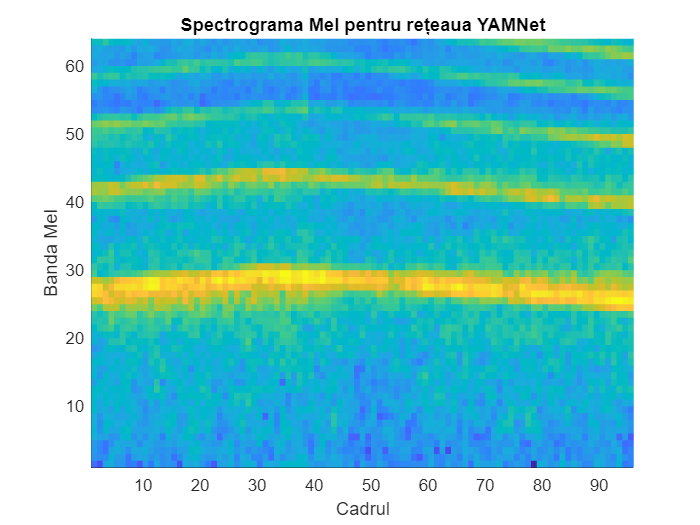

% Provide the correct file path
netFilePath = "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\mix.mat";    

% Read the .wav file
[audioIn, fs] = audioread('mix.wav');

spectrograms = yamnetPreprocess(audioIn,fs);

arbitrarySpect = spectrograms(:,:,1,randi(size(spectrograms,4)));
surf(arbitrarySpect,EdgeColor="none")
view([90 -90])
xlabel("Banda Mel")
ylabel("Cadrul")
title("Spectrograma Mel pentru rețeaua YAMNet")
axis tight


% Load the MAT file and check its contents
loadedData = load(netFilePath);


% This will display the variables stored in the MAT file
% Find the variable name that corresponds to your network model

% Assuming the network model is stored in a variable named 'model' in the MAT file
net = loadedData.mix;

% Now, you can proceed with classification
tic;
[YPred,probs] = classify(net, spectrograms);
timp_inferenta=toc;

% Display the predictions

fprintf('Clasa de sunet: %s\n', YPred(1));

Clasa de sunet: siren


fprintf('Timp inferență: %.4f seconds\n', timp_inferenta);

Timp inferență: 0.6344 seconds


## Filtrare / VAD

Puterea zgomotului de fundal înainte de atenuare: -11.3485 dB


Puterea zgomotului de fundal după atenuare: -17.3485 dB


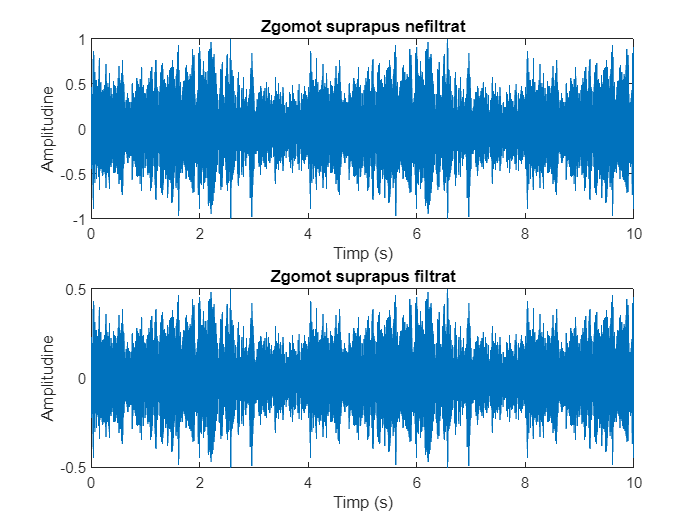

 

% Numele fișierelor de intrare
recordedFile = 'mix.wav';
filename_zgomot = 'noise_extended.wav';

% Citirea fișierelor audio
[x1, fs1] = audioread('mix.wav');
[x2, fs2] = audioread('noise_extended.wav');

% Verificarea că frecvențele de eșantionare sunt aceleași
if fs1 ~= fs2
    error('Frecvențele de eșantionare ale celor două fișiere sunt diferite.');
end

% Definire parametri comuni
fs = fs1;
order = 4; % Ordinul filtrului

t = (0:length(x1)-1)/fs;

% Aplicarea filtrului pe baza valorii YPred(1)
if strcmp(YPred(1), 'engine_idling_voce') || strcmp(YPred(1), 'jackhammer_voce')
    % Highpass Butterworth pentru componenta de 80 Hz
    cutoff_freq = 80; % Frecvența de tăiere
    Wn = cutoff_freq / (fs / 2);
    [b, a] = butter(order, Wn, 'high');
    
    % Aplicarea filtrului pe semnale
    y1 = filter(b, a, x1);
    y2 = filter(b, a, x2);
    
    plot(t, x1);
    title('Înregistrare vocală cu zgomot suprapus nefiltrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    plot(t, y1);
    title('Înregistrare vocală cu zgomot suprapus filtrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    disp(['Fișierele filtrate au fost salvate ca: ', recordedFile, ' și ', filename_zgomot]);

elseif strcmp(YPred(1), 'siren_voce')
    % Bandstop Butterworth centrat pe 800 Hz
    f0 = 800; % Frecvența centrală a filtrului oprește bandă
    bw = 200; % Lățimea benzii de oprire (în Hz)
    Wn = [(f0 - bw/2)/(fs/2), (f0 + bw/2)/(fs/2)];
    [b, a] = butter(order, Wn, 'stop');
    
    % Aplicarea filtrului pe semnale
    y1 = filter(b, a, x1);
    y2 = filter(b, a, x2);

    plot(t, x1);
    title('Înregistrare vocală cu zgomot suprapus nefiltrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    plot(t, y1);
    title('Înregistrare vocală cu zgomot suprapus filtrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    disp(['Fișierele filtrate au fost salvate ca: ', recordedFile, ' și ', filename_zgomot]);

else
    
    % Atenuare de 6 dB pentru zgomot de fundal
    atenuare = 10^(-6/20);
    
    if size(x1, 2) == 2
        x1 = mean(x1, 2);
    end
    if size(x2, 2) == 2
        x2 = mean(x2, 2);
    end

    % Aplicarea atenuării pe semnalele noastre
    y1 = x1 * atenuare;
    y2 = x2 * atenuare;
    putere_inainte = mean(x1.^2);
    putere_dupa = mean(y1.^2);

    putere_inainte_dB = 10 * log10(putere_inainte);
    putere_dupa_dB = 10 * log10(putere_dupa);

    disp(['Puterea zgomotului de fundal înainte de atenuare: ', num2str(putere_inainte_dB), ' dB']);
    disp(['Puterea zgomotului de fundal după atenuare: ', num2str(putere_dupa_dB), ' dB']);

    figure;
    subplot(2, 1, 1);
    plot(t, x1);
    title('Zgomot suprapus nefiltrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    subplot(2,1,2);
    plot(t, y1);
    title('Zgomot suprapus filtrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
end


% Suprascrierea fișierelor audio filtrate
audiowrite(recordedFile, y1, fs);
audiowrite(filename_zgomot, y2, fs);




## Filtrarea adaptivă a înregistrării

 
% Read the .wav files
[signal, fs_signal] = audioread('mix.wav');
[noise, fs_noise] = audioread('noise_extended.wav');

% If the audio files are stereo, convert them to mono
if size(signal, 2) == 2
    signal = mean(signal, 2);  % Convert to mono by averaging channels
end
if size(noise, 2) == 2
    noise = mean(noise, 2);  % Convert to mono by averaging channels
end

% Ensure both signals are of the same length
minLength = min(length(signal), length(noise));
signal = signal(1:minLength);
noise = noise(1:minLength);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Calculate the autocorrelation
acf = xcorr(signal, 'coeff');

% Extract the autocorrelation value at zero lag
Rxx = mean(acf);

% % Display the autocorrelation value at zero lag
% disp(['Autocorrelation at zero lag (Rxx): ', num2str(Rxx)]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create a dsp.LMSFilter object with a specific step size and filter length
filterLength = 64;
mu = 0.0001; % Step size
lms = dsp.LMSFilter('Length', filterLength, 'StepSize', mu);

if strcmp(YPred(1), 'engine_idling_voce') || strcmp(YPred(1), 'jackhammer_voce') || strcmp(YPred(1), 'siren_voce')

    % Calculate SNR before filtering
    SNR_dB_before = snr(signal, noise);
    disp(['Raport semnal-zgomot înainte de filtrare [dB]: ', num2str(SNR_dB_before)]);
    
    % Use the LMS filter to filter the noise from the signal
    [e, y] = lms(noise, signal);
    
    % Write the filtered error signal to a new .wav file
    audiowrite('zgomot_izolat.wav', e, fs_signal);
    
    % Calculate the filtered signal
    filtered_signal = signal - e;
    
    % Write the filtered signal to a new .wav file
    audiowrite('audio_filtrat.wav', filtered_signal, fs_signal);
    
    % Calculate SNR after filtering
    noise_residual = signal - filtered_signal;
    SNR_dB_after = snr(signal, noise_residual);
    disp(['Raport semnal-zgomot după filtrare [dB]: ', num2str(SNR_dB_after)]);
    
    % Time vector for plotting
    t = (0:length(signal)-1) / fs_signal;
    
    % Plot the original, filtered, and error signals
    figure;
    subplot(4,1,1);
    plot(t, signal);
    title('Semnal audio nefiltrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    subplot(4,1,2);
    plot(t, e);
    title('Zgomotul extras izolat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    subplot(4,1,3);
    plot(t, filtered_signal);
    title('Semnal filtrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

end